load("Img_and_scan.mat");
image_compressed.Format = 'bgr8; jpeg compressed bgr8';
image = readImage(image_compressed)

image = 480×640×3 uint8 array
image(:,:,1) =

   162   162   162   162   162   162   162   162   162   162   162   162   162   162   162   161   156   158   163   168   172   170   166   158   146   138   135   132   125   118   113   112   114   115   116   116   116   115   113   113   110   110   110   110   110   111   111   111   108   107   107   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   106   105   105   105   105   104   104   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   104   104   105   105   105   105   106   106   106   106   106   106   107   107   107

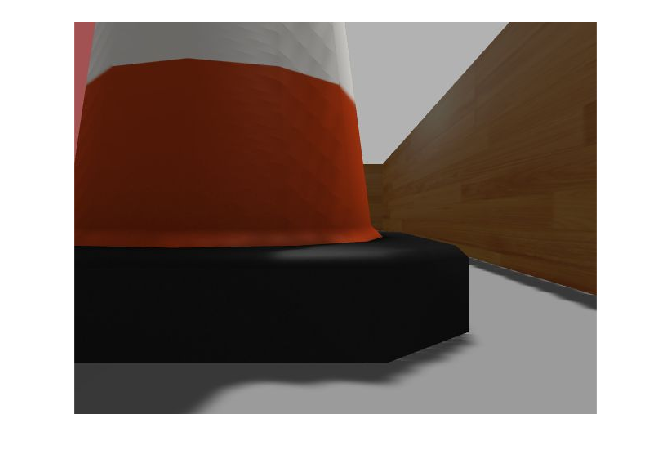

imshow(image);

## Find only lidar points in Camera FoV

num_ranges = length(scan_data.Ranges);

cam_horz_FoV = 54; % Degrees
half_cam_horz_FoV = cam_horz_FoV /2;


% Assumption is that there is a lidar point at each degree
left_points = scan_data.Ranges(1:half_cam_horz_FoV);
right_points = scan_data.Ranges(num_ranges - half_cam_horz_FoV +2:num_ranges);

## Camera Parameters

focal_length = 3.6 * 10^-3; % Meters
pixels_per_compress_pixel = 2592/640;
pixel_w_h = pixels_per_compress_pixel*0.0000014; % Meters

% right to left loop over points
scan_points = [right_points;left_points];
columns = [];
for j = 1:length(scan_points)
    if isnan(scan_points(j)) || isinf(scan_points(j))
        continue
    end
    angle = -half_cam_horz_FoV + j*1;
    scan_points(j);
    atan_gamma_c_num = scan_points(j)*sin(deg2rad(angle));
    atan_gamma_c_den = scan_points(j)*cos(deg2rad(angle));
    gamma_C = atan2(atan_gamma_c_num, ...
        atan_gamma_c_den)

    column = -(focal_length *  sin(gamma_C) / pixel_w_h) + 320;
    columns = [columns column];
    
end

gamma_C = single
-0.4538

gamma_C = single
-0.4363

gamma_C = single
-0.4189

gamma_C = single
-0.4014

gamma_C = single
-0.3840

gamma_C = single
-0.3665

gamma_C = single
-0.3491

gamma_C = single
-0.3316

gamma_C = single
-0.3142

gamma_C = single
-0.2967

gamma_C = single
-0.2793

gamma_C = single
-0.2618

gamma_C = single
-0.2443

gamma_C = single
-0.2269

gamma_C = single
-0.2094

gamma_C = single
-0.1920

gamma_C = single
-0.1745

gamma_C = single
-0.1571

gamma_C = single
-0.1396

gamma_C = single
-0.1222

gamma_C = single
-0.1047

gamma_C = single
-0.0873

gamma_C = single
-0.0698

gamma_C = single
-0.0524

gamma_C = single
-0.0349

gamma_C = single
-0.0175

gamma_C = single
0

gamma_C = single
0.0175

gamma_C = single
0.0349

gamma_C = single
0.0524

gamma_C = single
0.0698

gamma_C = single
0.0873

gamma_C = single
0.1047

gamma_C = single
0.1222

gamma_C = single
0.1396

gamma_C = single
0.1571

gamma_C = single
0.1745

gamma_C = single
0.1920

gamma_C = single
0.2094

gamma_C = single
0.2269

gamma_C = single
0.2443

gamma_C = single
0.2618

gamma_C = single
0.2793

gamma_C = single
0.2967

gamma_C = single
0.3142

gamma_C = single
0.3316

gamma_C = single
0.3491

gamma_C = single
0.3665

gamma_C = single
0.3840

gamma_C = single
0.4014

gamma_C = single
0.4189

gamma_C = single
0.4363

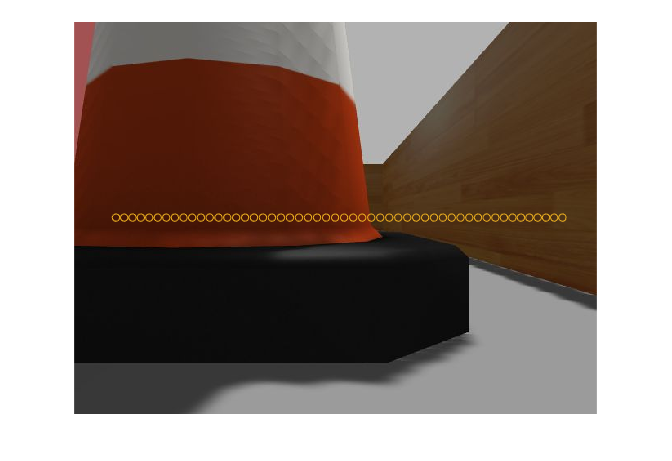

Unrecognized function or variable 'fig'.


figure; imshow(image); hold on;
scatter(columns, zeros(length(columns))+240)

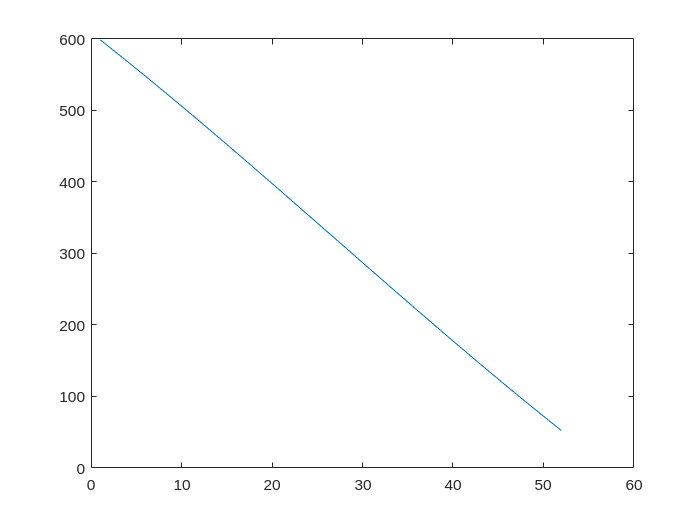

figure; plot(columns)